# TTD lines evaluations

**Description**: This code reads parameters file "parameters_cao2022broadband.txt" to evaluate the length of the true-time delay (TTD) lines. The geometry followed in this code is the Type-1 TTD, as illustrated in Fig. 7, as follows from [1].

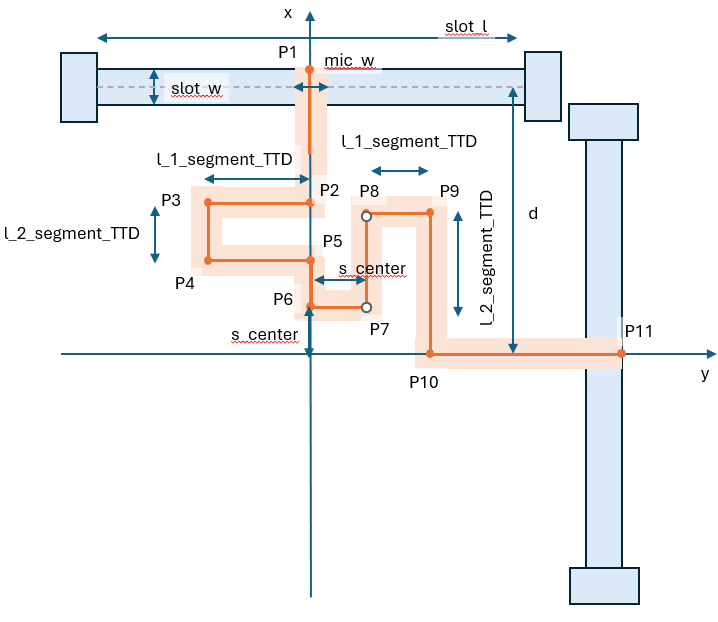

Figure 7 Coordinates to implement the center line for the TTDs

clear; clc;
 
% ---- USER INPUTS ------------------------------------------------------
params_file    = 'parameters_cao2022broadband_TTD_type_2.txt';                % file written by CST

polyline_file  = 'L5_TTD_A_Type_2_polygon_CST_xyz_triplets.txt';

% -----------------------------------------------------------------------
 
pat = '^\s*([A-Za-z_][A-Za-z_0-9]*)\s*=\s*"([^"]*)"\s*(?:"([^"]*)")?\s*$';
 
% ---- Read parameters file, detect CRLF --------------------------------
fid = fopen(params_file, 'rb');
if fid < 0, error('Cannot open %s', params_file); end
raw_bytes = fread(fid, Inf, 'uint8=>char')';
fclose(fid);
 
if ~isempty(strfind(raw_bytes, sprintf('\r\n')))
    eol = sprintf('\r\n');
else
    eol = sprintf('\n');
end
 
raw_lines = regexp(raw_bytes, '\r?\n', 'split');
if ~isempty(raw_lines) && isempty(raw_lines{end}), raw_lines(end) = []; end
 
% ---- Parse parameters file: key -> value lookup -----------------------
pat_with    = '^\s*([A-Za-z_][A-Za-z_0-9]*)\s*=\s*"([^"]*)"\s+"([^"]*)"\s*$';
pat_without = '^\s*([A-Za-z_][A-Za-z_0-9]*)\s*=\s*"([^"]*)"\s*$';

keys = {}; vals = {}; cmts = {};
for i = 1:numel(raw_lines)
    L = raw_lines{i};
    tok = regexp(L, pat_with, 'tokens', 'once');
    if ~isempty(tok)
        cmt = tok{3};
    else
        tok = regexp(L, pat_without, 'tokens', 'once');
        if isempty(tok), continue; end
        cmt = '';
    end
    if ~any(strcmp(keys, tok{1}))
        keys{end+1,1} = tok{1};
        vals{end+1,1} = tok{2};
        cmts{end+1,1} = cmt;
    end
end
 

% ---- Helper: numeric lookup -------------------------------------------
get_num = @(name) str2double(vals{find(strcmp(keys, name), 1, 'first')});
 
d      = get_num('d');
slot_l = get_num('slot_l');
mic_w  = get_num('mic_w');
a      = get_num('a');
db_l      = get_num('m_l');
db_w      = get_num('m_w');
slot_w      = get_num('slot_w');
 
if any(isnan([d, slot_l, mic_w, a]))
    error('Could not read numeric d / slot_l / mic_w / a from %s', params_file);
end
 
% ---- Type-1 calculations -------------------------------------------------

 
% ---- Write the parameters file with reference comments ----------------
s_center=4*mic_w;
updates = struct('s_center', sprintf('%.6g', s_center));
upd_keys = fieldnames(updates);
 
fid = fopen(params_file, 'wb');
if fid < 0, error('Cannot write %s', params_file); end
for i = 1:numel(raw_lines)
    L = raw_lines{i};
    tok = regexp(L, pat_with, 'tokens', 'once');
    if isempty(tok)
        fwrite(fid, [L eol]);
        continue;
    end
    key = tok{1}; val = tok{2};
    if numel(tok) >= 3, cmt = tok{3}; else, cmt = ''; end
 
    % overwrite numeric s_center with computed values
    if any(strcmp(upd_keys, key)) && ~isnan(str2double(val))
        val = updates.(key);
    end
    
    if isempty(cmt)
        new_line = sprintf('%s="%s"', key, val);
    else
        new_line = sprintf('%s="%s" "%s"', key, val, cmt);
    end

    fwrite(fid, [new_line eol]);
end
fclose(fid);
fprintf('Wrote %s\n', params_file);

Wrote parameters_cao2022broadband_TTD_type_2.txt



P1= 'd+slot_w/2                                        0                         (z_L5+z_L6)/2';
P2= 'd-slot_w/2-1/2*mic_w-1/8*mic_w                    0                         (z_L5+z_L6)/2';
P3= 'd-slot_w/2-1/2*mic_w-1/8*mic_w                   -l_1_segment_TTD           (z_L5+z_L6)/2';
P4= 'd-slot_w/2-1/2*mic_w-1/8*mic_w-l_2_segment_TTD   -l_1_segment_TTD           (z_L5+z_L6)/2';
P5= 'd-slot_w/2-1/2*mic_w-1/8*mic_w-l_2_segment_TTD    0                         (z_L5+z_L6)/2';
P6= 's_center                                          0                         (z_L5+z_L6)/2';
P7= 's_center                                          s_center                  (z_L5+z_L6)/2';
P8= 'l_2_segment_TTD                                   s_center                  (z_L5+z_L6)/2';
P9= 'l_2_segment_TTD                                   s_center+l_1_segment_TTD  (z_L5+z_L6)/2';
P10='0                                                 s_center+l_1_segment_TTD  (z_L5+z_L6)/2';
P11='0                                                 d+slot_w/2                (z_L5+z_L6)/2';

% ---- Regenerate the polyline file (symbolic, slot-centre pinned) ------
poly_lines = { P1, P2, P3, P4, P5, P6, P7, P8, P9, P10, P11};
 
fid = fopen(polyline_file, 'wb');
if fid < 0, error('Cannot write %s', polyline_file); end
for k = 1:numel(poly_lines), fwrite(fid, [poly_lines{k} eol]); end


#### Version 2 with four segments

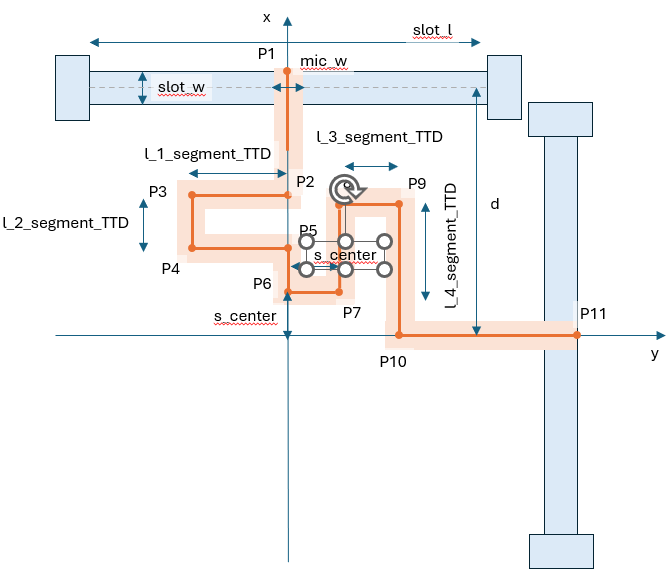



P1= 'd+slot_w/2                                        0                         (z_L5+z_L6)/2';
P2= 'd-slot_w/2-1/2*mic_w-1/8*mic_w                    0                         (z_L5+z_L6)/2';
P3= 'd-slot_w/2-1/2*mic_w-1/8*mic_w                   -l_1_segment_TTD           (z_L5+z_L6)/2';
P4= 'd-slot_w/2-1/2*mic_w-1/8*mic_w-l_2_segment_TTD   -l_1_segment_TTD           (z_L5+z_L6)/2';
P5= 'd-slot_w/2-1/2*mic_w-1/8*mic_w-l_2_segment_TTD    0                         (z_L5+z_L6)/2';
P6= 's_center                                          0                         (z_L5+z_L6)/2';
P7= 's_center                                          s_center                  (z_L5+z_L6)/2';
P8= 'l_4_segment_TTD                                   s_center                  (z_L5+z_L6)/2';
P9= 'l_4_segment_TTD                                   s_center+l_3_segment_TTD  (z_L5+z_L6)/2';
P10='0                                                 s_center+l_3_segment_TTD  (z_L5+z_L6)/2';
P11='0                                                 d+slot_w/2                (z_L5+z_L6)/2';

% ---- Regenerate the polyline file (symbolic, slot-centre pinned) ------
poly_lines = { P1, P2, P3, P4, P5, P6, P7, P8, P9, P10, P11};
 
fid = fopen(polyline_file, 'wb');
if fid < 0, error('Cannot write %s', polyline_file); end
for k = 1:numel(poly_lines), fwrite(fid, [poly_lines{k} eol]); end



#### Version 3 with six segments

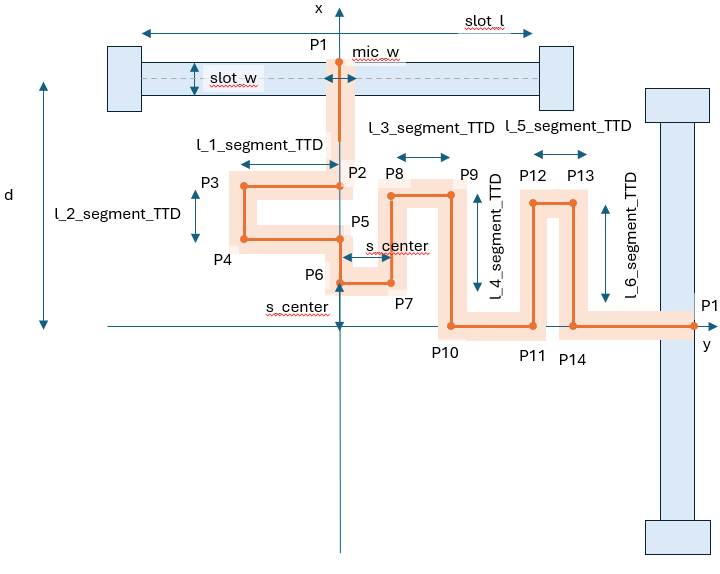



P1= 'd+slot_w/2                                        0                                 (z_L5+z_L6)/2';
P2= 'd-slot_w/2-1/2*mic_w-1/8*mic_w                    0                                 (z_L5+z_L6)/2';
P3= 'd-slot_w/2-1/2*mic_w-1/8*mic_w                   -l_1_segment_TTD                   (z_L5+z_L6)/2';
P4= 'd-slot_w/2-1/2*mic_w-1/8*mic_w-l_2_segment_TTD   -l_1_segment_TTD                   (z_L5+z_L6)/2';
P5= 'd-slot_w/2-1/2*mic_w-1/8*mic_w-l_2_segment_TTD    0                                 (z_L5+z_L6)/2';
P6= 's_center                                          0                                 (z_L5+z_L6)/2';
P7= 's_center                                          s_center                          (z_L5+z_L6)/2';
P8= 'l_4_segment_TTD                                   s_center                          (z_L5+z_L6)/2';
P9= 'l_4_segment_TTD                                   s_center+l_3_segment_TTD          (z_L5+z_L6)/2';
P10='0                                                 s_center+l_3_segment_TTD          (z_L5+z_L6)/2';
P11='0                                                 d+slot_w/2+mic_w                  (z_L5+z_L6)/2';
P12='l_6_segment_TTD                                   d+slot_w/2+mic_w                  (z_L5+z_L6)/2';
P13='l_6_segment_TTD                                   d+slot_w/2+mic_w+l_5_segment_TTD  (z_L5+z_L6)/2';
P14='0                                                 d+slot_w/2+mic_w+l_5_segment_TTD  (z_L5+z_L6)/2';
P15='0                                                 d+slot_w/2                        (z_L5+z_L6)/2';

% ---- Regenerate the polyline file (symbolic, slot-centre pinned) ------
poly_lines = { P1, P2, P3, P4, P5, P6, P7, P8, P9, P10, P11, P12, P13, P14, P15};
 
fid = fopen(polyline_file, 'wb');
if fid < 0, error('Cannot write %s', polyline_file); end
for k = 1:numel(poly_lines), fwrite(fid, [poly_lines{k} eol]); end

fclose(fid);
fprintf('Wrote %s\n', polyline_file);

Wrote L5_TTD_A_Type_2_polygon_CST_xyz_triplets.txt


#### References

[1] A Broadband Low-Profile Transmitarray Antenna by Using Differentially Driven Transmission Polarizer With True-Time Delay